## [Maintain Glucose in Type-I Diabetic](https://apmonitor.com/pdc/index.php/Main/DiabeticBloodGlucose)

This assignment is to design an artificial pancreas for a Type-I diabetic. A Type-I diabetic has no insulin production in the pancreas. Insulin production in the pancreas is used to regulate a person’s blood glucose level. When that natural production does not exist, glucose is monitored at regular intervals and insulin is injected as needed. With the recent development of continuous blood glucose monitors and the established success of continuous insulin pumps, it is now possible to create a controller that automatically regulates blood glucose by adjusting the injection rate of insulin.

This development is needed because of the increased rates of diabetes within the U.S. as tracked by the Center for Disease Control (CDC). The incidence of diabetes mellitus is predicted to be 33% by 2050 if current trends continue. Currently 8-9% or 26 million Americans are affected by this condition with yearly direct medical costs of $116 billion and even higher indirect costs.

The set point for blood glucose concentration is expected to remain within a specified range that is typical of a healthy individual. A typical range for a healthy individual is between 64 and 104 mg/dL (3.6 and 5.8 mmol/L) with a target of 80 mg/dL. Blood glucose values that are out of range are undesirable but values that are too low are much more serious and can lead to hospitalization or death if left untreated.

The insulin pump is a continuous injection into the person’s body. It can deliver flow rates between 0.0 and 10.0 \muU/min with a typical base value of 3.0 \muU/min. The controller must restrict values of the flow to this range during the controller testing although it is typical with these devices to allow small one-time injections when needed.

Determine FOPDT Model

Perform the necessary open loop dynamic modeling studies to determine a first order plus dead time (FOPDT) model which describes process operation near the design operation conditions (use the first 7 hours of data without meal disturbances). Report values of $K_p$, $\tau_p$ and $\theta_p$.

% Steady State Initial Conditions for the States
y0 = [76.22, 33.33, 33.33,16.67,16.67,250.0];

% Steady State Initial Condition for the Control
u_ss = 3.0; % mU/min

% Steady State for the Disturbance
d_ss = 1000.0; % mmol/L-min

% Final Time (hr)
tf = 24;      % simulate for 24 hours
ns = tf*6+1;  % sample time = 10 min

% Time Interval (min)
t = linspace(0,tf,ns);
Ts = t(2) -t(1);

% Store results for plotting
G = ones(length(t),1) * y0(1);
X = ones(length(t),1) * y0(2);
I = ones(length(t),1) * y0(3);
u = ones(length(t),1) * u_ss;
d = ones(length(t),1) * d_ss;

% Step response for insulin
u(11:end) = 2.8;

% Add meal disturbances
meals = [1259,1451,1632,1632,1468,1314,1240,1187,1139,1116, ...
          1099,1085,1077,1071,1066,1061,1057,1053,1046,1040, ...
          1034,1025,1018,1010,1000,993,985,976,970,964,958, ...
          954,952,950,950,951,1214,1410,1556,1603,1445,1331, ...
          1226,1173,1136,1104,1088,1078,1070,1066,1063,1061, ...
          1059,1056,1052,1048,1044,1037,1030,1024,1014,1007, ...
          999,989,982,975,967,962,957,953,951,950,1210,1403, ...
          1588,1593,1434,1287,1212,1159,1112,1090,1075,1064, ...
          1059,1057,1056,1056,1056,1055,1054,1052,1049,1045, ...
          1041,1033,1027,1020,1011,1003,996,986];

meals =         1259        1451        1632        1632        1468        1314        1240        1187        1139        1116        1099        1085        1077        1071        1066        1061        1057        1053        1046        1040        1034        1025        1018        1010        1000         993         985         976         970         964         958         954         952         950         950         951        1214        1410        1556        1603        1445        1331        1226        1173        1136        1104        1088        1078        1070        1066


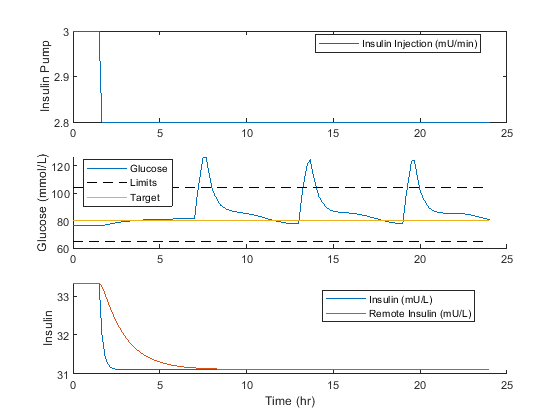

for i = 1:length(meals)
    d(i+43) = meals(i);
end

% Simulate Type-I Diabetic Blood Glucose
for i = 1:(length(t)-1)
    [a, y] = ode45(@(a, y) diabetic(a, y, u(i+1), d(i+1)),[0,Ts], y0);
    G(i+1) = y(end, 1);
    X(i+1) = y(end, 2);
    I(i+1) = y(end, 3);
    y0 = y(end,:);
end

subplot(3,1,1)
    p1 = plot(t,u);
    ylabel('Insulin Pump')
    legend(p1, 'Insulin Injection (mU/min)','Location', 'best')
subplot(3,1,2)
    hold on
    p2 = plot(t,G);
    p3 = plot([0,24],[104,104],'k--');
    p4 = plot([0,24],[80,80]);
    p5 = plot([0,24],[65,65],'k--');
    legend([p2, p3, p4],{'Glucose','Limits','Target'},'Location', 'best')
    ylabel('Glucose (mmol/L)')
subplot(3,1,3)
    hold on
    p6 = plot(t,I);
    p7 = plot(t,X);
    legend([p6, p7],{'Insulin (mU/L)','Remote Insulin (mU/L)'},'Location', 'best')
    ylabel('Insulin')
    xlabel('Time (hr)')

**Determine Initial PID Tuning**

Using the $K_p$, $\tau_p$, and $\theta_p$, compute the tuning parameters for a PID controller from the IMC tuning correlation. Report the tuning parameters.

**Implement PID Controller**

Using $K_c$, $\tau_I$, and $\tau_D$, implement a PID with anti-reset windup. Test the disturbance rejection capability of this controller by plotting the response of the process to meal disturbances. Comment on how the nonlinear behavior of this process impacts our observed disturbance rejection performance. Turn in a plot for the default IMC parameters, along with comments.

**Tune PID Controller**

Determine a *best* tuning by adjusting $K_c$, $\tau_I$, and $\tau_D$ until the controller response is improved (use quantitative measures like time outside the upper and lower limits). Plot the best disturbance rejection response. Turn in final plot and values of tuning parameters.

**Generate Tuning Sensitivity Guide**

Run six tuning cases and plot the response of each compared to the tuned controller. The first two cases should use the best $\tau_I$ and $\tau_D$ but should use double and then half of the best $K_c$. The next two cases should use the best $K_c$ and $\tau_D$, but should use double and then half of the best $\tau_I$. The final two cases should use the best $K_c$ and $\tau_I$, but should use double and then half of the best $\tau_D$. Comment on how the tuning parameters interact and impact controller performance. Turn in plots along with comments. Put all trends for each parameter on one plot for the sake of direct comparison.

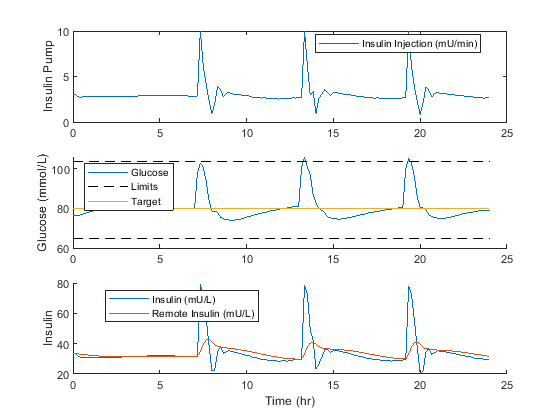

clc
clear
clf
% Steady State Initial Conditions for the States
y0 = [76.22, 33.33, 33.33,16.67,16.67,250.0];

% Steady State Initial Condition for the Control
u_ss = 3.0; % mU/min

% Steady State for the Disturbance
d_ss = 1000.0; % mmol/L-min

% Final Time (hr)
tf = 24;      % simulate for 24 hours
ns = tf*6+1;  % sample time = 10 min

% Time Interval (min)
t = linspace(0,tf,ns);
Ts = t(2) -t(1);

% Store results for plotting
G = ones(length(t),1) * y0(1);
X = ones(length(t),1) * y0(2);
Insulin = ones(length(t),1) * y0(3);
u = ones(length(t),1) * u_ss;
d = ones(length(t),1) * d_ss;

% Step response for insulin
u(11:end) = 2.0;

% Add meal disturbances
meals = [1259,1451,1632,1632,1468,1314,1240,1187,1139,1116, ...
          1099,1085,1077,1071,1066,1061,1057,1053,1046,1040, ...
          1034,1025,1018,1010,1000,993,985,976,970,964,958, ...
          954,952,950,950,951,1214,1410,1556,1603,1445,1331, ...
          1226,1173,1136,1104,1088,1078,1070,1066,1063,1061, ...
          1059,1056,1052,1048,1044,1037,1030,1024,1014,1007, ...
          999,989,982,975,967,962,957,953,951,950,1210,1403, ...
          1588,1593,1434,1287,1212,1159,1112,1090,1075,1064, ...
          1059,1057,1056,1056,1056,1055,1054,1052,1049,1045, ...
          1041,1033,1027,1020,1011,1003,996,986];
for i = 1:length(meals)
    d(i+43) = meals(i);
end

% storage for recording values
op = ones(ns+1,1)*u(1);  % controller output
pv = zeros(ns+1,1);  % process variable
e = zeros(ns+1,1);   % error
ie = zeros(ns+1,1);  % integral of the error
dpv = zeros(ns+1,1); % derivative of the pv
P = zeros(ns+1,1);   % proportional
I = zeros(ns+1,1);   % integral
D = zeros(ns+1,1);   % derivative
sp = ones(ns+1,1)* 80;  % set point

% PID (tuning)
Kc = -2.76E-02 * 2;
tauI = 0.5;
tauD = 1.0;

% Upper and Lower limits on OP
op_hi = 10.0;
op_lo = 0.0;

% Simulate Type-I Diabetic Blood Glucose
for i = 1:(length(t)-1)
    ts = [t(i),t(i+1)];
    delta_t = t(i+1)-t(i);

    pv(i) = G(i);
    e(i) = sp(i) - pv(i);
    if i >= 2  % calculate starting on second cycle
        dpv(i) = (pv(i)-pv(i-1))/delta_t;
        ie(i) = ie(i-1) + e(i) * delta_t;
    P(i) = Kc * e(i);
    I(i) = Kc/tauI * ie(i);
    D(i) = - Kc * tauD * dpv(i);
    op(i) = op(1) + P(i) + I(i) + D(i);
    end
    if op(i) > op_hi  % check upper limit
        op(i) = op_hi;
        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup
    end
    if op(i) < op_lo % check lower limit
        op(i) = op_lo;
        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup
    end
    u(i+1) = op(i);

    [a, y] = ode45(@(a, y) diabetic(a, y, u(i+1), d(i+1)),[0,Ts], y0);
    G(i+1) = y(end, 1);
    X(i+1) = y(end, 2);
    Insulin(i+1) = y(end, 3);
    y0 = y(end,:);
end
    
subplot(3,1,1)
    p1 = plot(t,u);
    ylabel('Insulin Pump')
    legend(p1, 'Insulin Injection (mU/min)','Location', 'best')
subplot(3,1,2)
    hold on
    p2 = plot(t,G);
    p3 = plot([0,24],[104,104],'k--');
    p4 = plot([0,24],[80,80]);
    p5 = plot([0,24],[65,65],'k--');
    legend([p2, p3, p4],{'Glucose','Limits','Target'},'Location', 'NorthWest')
    ylabel('Glucose (mmol/L)')
subplot(3,1,3)
    hold on
    p6 = plot(t,Insulin(1:length(t)));
    p7 = plot(t,X);
    legend([p6, p7],{'Insulin (mU/L)','Remote Insulin (mU/L)'},'Location', 'best')
    ylabel('Insulin')
    xlabel('Time (hr)')

function dydt = diabetic(a,y,ui,d)
    % Inputs (2)
    % U = Insulin infusion rate (mU/min)
    % D = Meal disturbance (mmol/L-min)

    % Expanded Bergman Minimal model to include meals and insulin
    % Parameters for an insulin dependent type-I diabetic

    % States (6):
    % In non-diabetic patients, the body maintains the blood glucose
    %  level at a range between about 3.6 and 5.8 mmol/L (64.8 and
    %  104.4 mg/dL with 1:18 conversion between mmol/L and mg/dL)
    g = y(1);                % blood glucose (mg/dL)
    x = y(2);                % remote insulin (micro-u/ml)
    i = y(3);                % insulin (micro-u/ml)
    q1 = y(4);
    q2 = y(5);
    g_gut = y(6);            % gut blood glucose (mg/dl)

    % Parameters:
    gb    = 291.0;           % Basal Blood Glucose (mg/dL)
    p1    = 3.17e-2;         % 1/min
    p2    = 1.23e-2;         % 1/min
    si    = 2.9e-2;          % 1/min * (mL/micro-U)
    ke    = 9.0e-2;          % 1/min
    kabs  = 1.2e-2;          % 1/min
    kemp  = 1.8e-1;          % 1/min
    f     = 8.00e-1;         % L
    vi    = 12.0;           % L
    vg    = 12.0;            % L

    % Compute ydot:
    dydt = zeros(6,1);
    dydt(1) = -p1*(g-gb) - si*x*g + f*kabs/vg * g_gut + f/vg * d;
    dydt(2) =  p2*(i-x); % remote insulin compartment dynamics
    dydt(3) = -ke*i + ui; % insulin dynamics
    dydt(4) = ui - kemp * q1;
    dydt(5) = -kemp*(q2-q1);
    dydt(6) = kemp*q2 - kabs*g_gut;

    % convert from minutes to hours
    dydt = dydt*60;
end